# TAREA 04

## Ejercicio 1

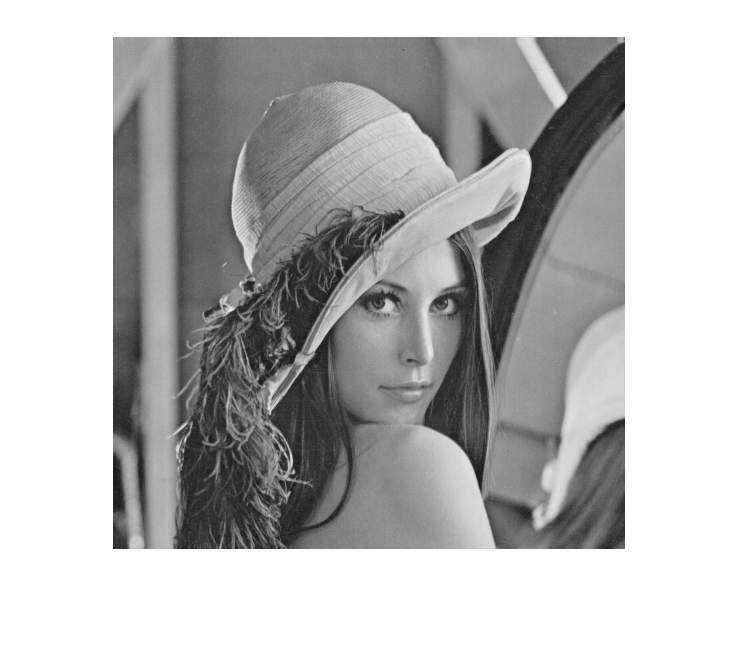


load lena512.mat 
imshow(uint8(lena512)) 

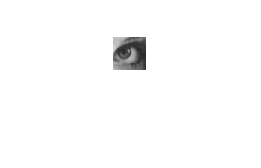

lenarec=lena512(252:284,318:350); 
imshow(uint8(lenarec)) 

b = de2bi(lenarec,8,'left-msb');
b=b'; 
bits=b(:);   % Vector de bits concatenado 
% Reconstruir la imagen 
bitsM = reshape(bits,8,1089);
bitsM = bitsM';
decval = bi2de(bitsM,'left-msb');
lenaRS = reshape(decval, size(lenarec));
imshow(uint8(lenaRS))

## Ejercicio 2: Unipolar NRZ

Fs= 96000;
mp= 20;
%No_bits= 8712;
Baud_rate= Fs/mp %Symbols per second

Baud_rate = 4800

Bit_rate=Baud_rate % bits/s

Bit_rate = 4800

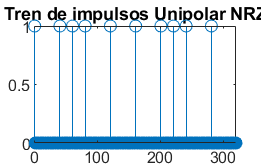

Ts=1/Fs;
% The bit rate is Rb= Rs= Fs / mp, because 1 bit= 1 symbol and  every symbol has mp
% samples per bit
%pnrz = [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]; % Pulse type with mp samples
pnrz =ones(1,mp); % Similar to Arduino pulses with 5V
%wvtool(pnrz)
s = zeros(1,numel(bits)*mp);
s(1:mp:end) = bits;   % Impulse Train
stem(s(1:mp*16))
title('Tren de impulsos Unipolar NRZ');

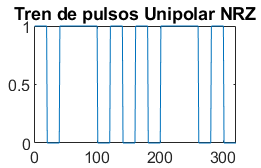

xUNRZ = conv(pnrz,s); % Pulse Train
plot(xUNRZ(1:mp*16))
title('Tren de pulsos Unipolar NRZ');

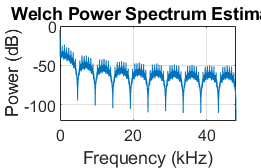

pwelch(xUNRZ,[],[],[],Fs,'power');  % PSD of Unipolar NRZ

%%wvtool(xUNRZ)

## Ejercicio 2: Polar NRZ

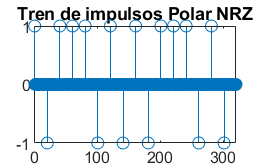

%Baud_rate= Fs/mp %Symbols per second
%Bit_rate=Baud_rate % bits/s
pnrz=ones(1,mp);
s1=bits;
s1(s1==0)=-1;
s=zeros(1,numel(s1)*mp);
s(1:mp:end)=s1; %Impulse train
stem(s(1:mp*16))
title('Tren de impulsos Polar NRZ');

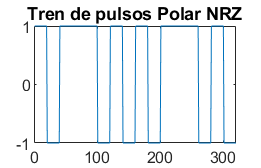

xPNRZ=conv(pnrz,s); %Pulse train
plot(xPNRZ(1:mp*16))
title('Tren de pulsos Polar NRZ');

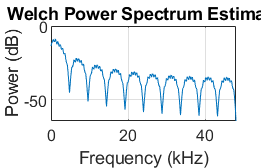

pwelch(xPNRZ,500,300,500,Fs,'power');

%%wvtool(xPNRZ)

## Ejercicio 2: Polar RZ

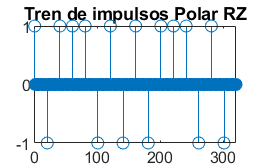

%Baud_rate= Fs/mp %Symbols per second
%Bit_rate=Baud_rate % bits/s
pprz=[ones(1,mp/2),zeros(1,mp/2)];
s1=int8(bits);
s1(bits==0)=-1;
s=zeros(1,numel(s1)*mp);
s(1:mp:end)=s1;
stem(s(1:mp*16))
title('Tren de impulsos Polar RZ');

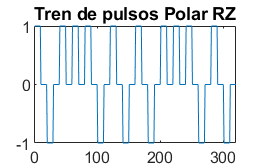

xprz=conv(pprz,s);
plot(xprz(1:mp*16));  % Show 16 symbols
title('Tren de pulsos Polar RZ');

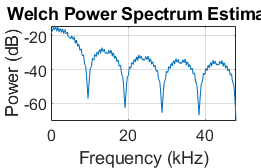

pwelch(xprz,500,300,500,Fs,'power');

%%wvtool(xprz)


## Ejercicio 2: Bipolar NRZ

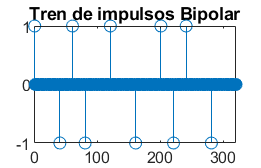


%Baud_rate= Fs/mp %Symbols per second
%Bit_rate=Baud_rate % bits/s
pAMI = [ones(1,mp),zeros(1,mp)];
s1 = bits;
flag = boolean(0);
for k= 1:numel(s1);
    if (s1(k)==1)
        if (flag == 1)
           s1(k)=-1;
        end
        flag = ~flag;
    end
end
s=zeros(1,numel(s1)*mp);
s(1:mp:end)=s1;
stem(s(1:mp*16))
title('Tren de impulsos Bipolar');

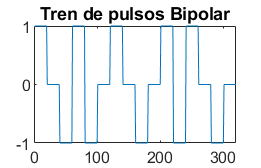

xAMI=conv(pAMI,s);
plot(xAMI(1:mp*16));  % Show 16 symbols
title('Tren de pulsos Bipolar');

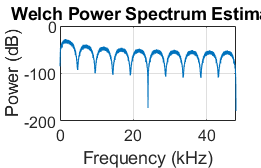

pwelch(xAMI, [],[],[],Fs,'power');

%%wvtool(xAMI)


## Ejercicio 2: Manchester

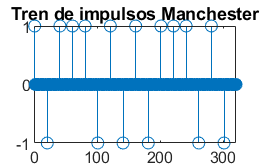

%Baud_rate= Fs/mp %Symbols per second
%Bit_rate=Baud_rate % bits/s
pm=[ones(1,mp/2),-1*ones(1,mp/2)]; 
s1=bits;
s1(s1==0)=-1;
s=zeros(1,numel(bits)*mp);
s(1:mp:end)=s1;
stem(s(1:mp*16))
title('Tren de impulsos Manchester');

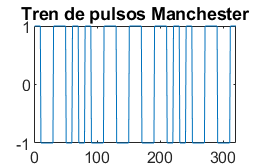

xm=conv(pm,s);
plot(xm(1:mp*16));  % Show 16 symbols
title('Tren de pulsos Manchester');

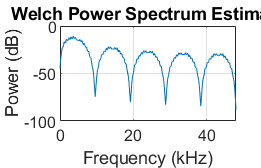

pwelch(xm,500,300,500,Fs,'power');

%%wvtool(xm)

